
%#ok<*CLALL>

clear all;clc 

gridSettings = gridSettingsClass; 

gridSettings.gridSize = [128, 256]; 

% Let 1 tick be 1 hour. 
gridSettings.ticksPerYear = 365*24; 

gridSettings.tickSpan = 1 : gridSettings.ticksPerYear; 

gridSettings.riskFactorMean = -1E-3; 
gridSettings.riskFactorStandardDeviation = 1E-3; 
gridSettings.riskFactorAmplitudeMean = 1E-3; 
gridSettings.riskFactorAmplitudeStandardDeviation = 1E-3/4; 

gridSettings.restoreGridHealthRate = 1/gridSettings.ticksPerYear; 

gridSettings.restoreGridHealthCost = 1; 

gridSettings.newFireIntensityMax = 1.5E-3; 
gridSettings.newFireIntensityMean = 1E-3; 
gridSettings.newFireIntensityStandardDeviation = 1E-3/4; 

gridSettings.fireIntensityScaler = 16; 
gridSettings.peakIntensityHealthMin = 0.5; 
gridSettings.peakIntensityHealthMax = 0.7; 
gridSettings.peakIntensityHealth_mean = 0.6; 
gridSettings.peakIntensityHealth_standardDeviation = 0.02; 

simGrid = gridClass(gridSettings); 

% Take a peek at grid block (5, 16): 
tspan = simGrid.tickSpan; 
% tspan = 1 : 2; 
riskFactorPeekaboo = zeros(size(tspan)).'; 
fireIntensityPeekaboo = zeros(size(tspan)).'; 
healthPeekaboo = zeros(size(tspan)).'; 
fireExistencePeekaboo = zeros(size(tspan)).'; 
tic; 
for tick = tspan
    simGrid.updateGrid(); 
    riskFactorPeekaboo(tick) = simGrid.riskFactor(5, 16); 
    fireIntensityPeekaboo(tick) = simGrid.fires.intensity(5, 16); 
    fireExistencePeekaboo(tick) = logical(simGrid.fires.intensity(5, 16)); 
    healthPeekaboo(tick) = simGrid.gridHealth(5, 16); 
end
toc; 

Elapsed time is 14.151216 seconds.


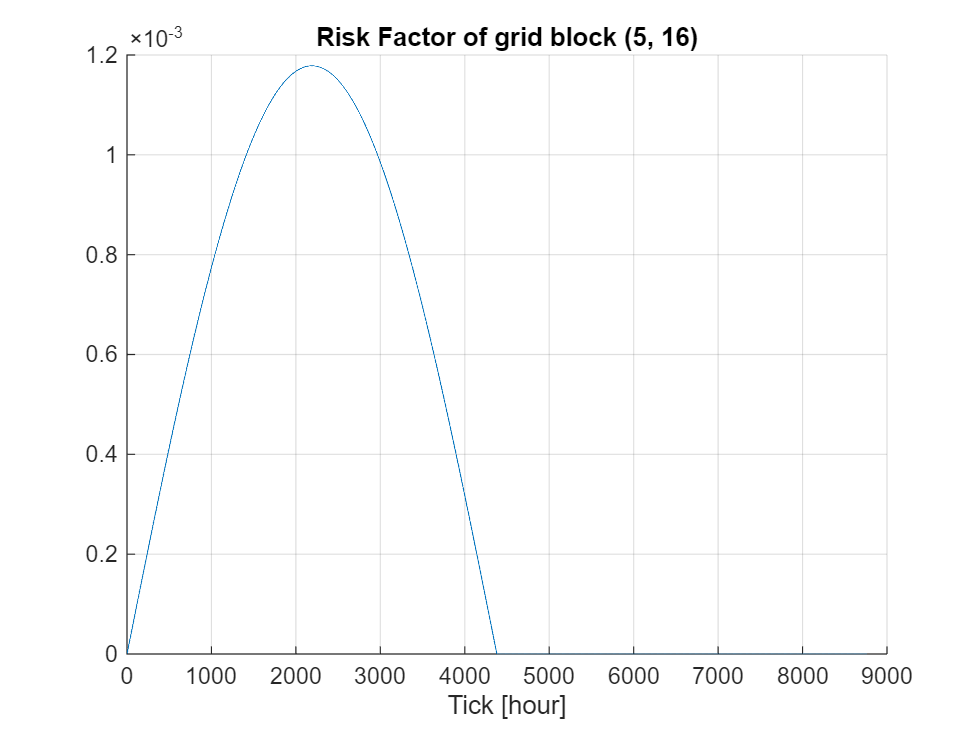

clf; 
hold on; 
grid on; 
plot(tspan, riskFactorPeekaboo); 
xlabel("Tick [hour]"); 
title("Risk Factor of grid block (5, 16)"); 
hold off; 

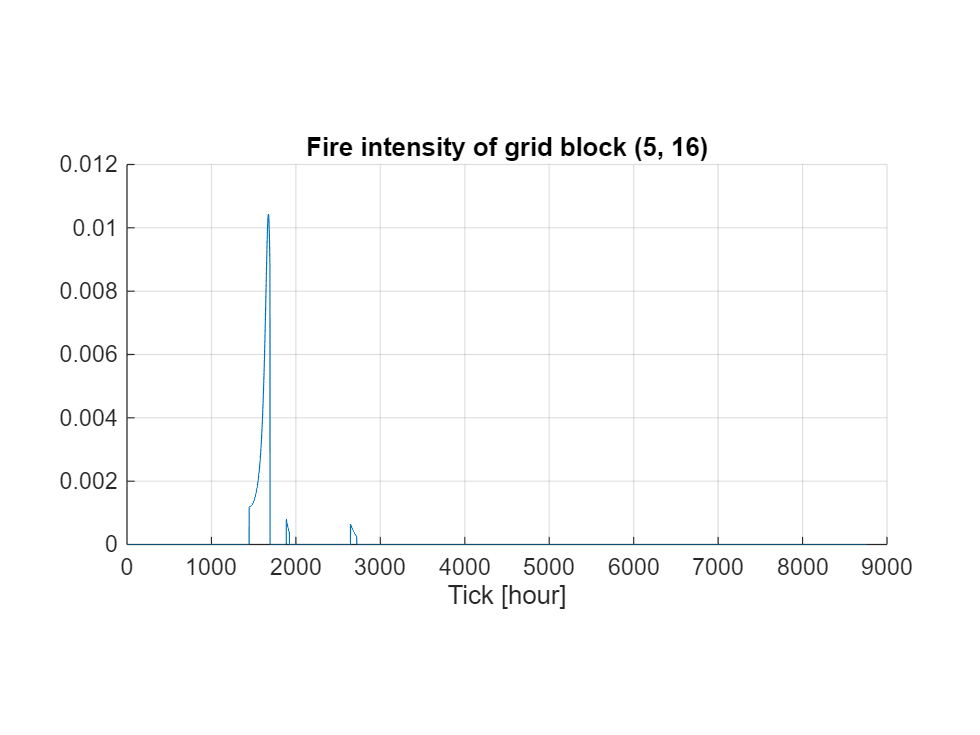

clf; 
hold on; 
grid on; 
plot(tspan, fireIntensityPeekaboo); 
xlabel("Tick [hour]"); 
title("Fire intensity of grid block (5, 16)"); 
pbaspect([2 1 1])
hold off; 

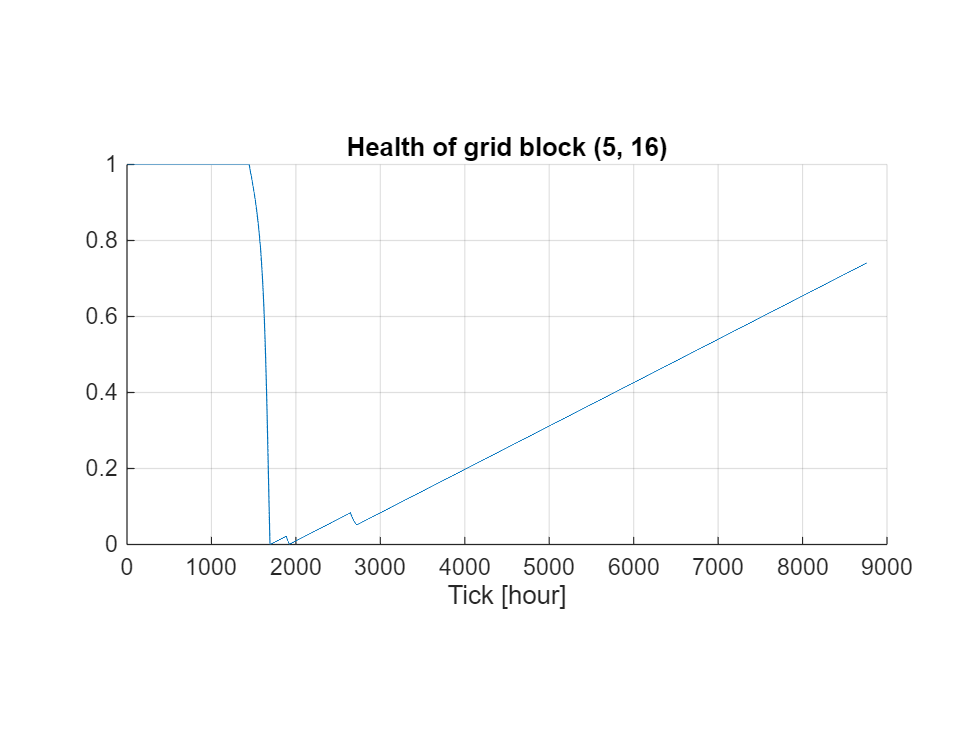

clf; 
hold on; 
grid on; 
plot(tspan, healthPeekaboo); 
xlabel("Tick [hour]"); 
title("Health of grid block (5, 16)"); 
pbaspect([2 1 1])
hold off; 